1.已知Griewank函数具有如下表达式：

$f(x)=\sum_{i=1}^{n} \frac{x_{i}^{2}}{4000}-\prod_{i=1}^{n} \cos \left(\frac{x_{i}}{\sqrt{i}}\right)+1, x=\left(x_{1}, x_{2}, \cdots, x_{n}\right) \in \mathbb{R}^{n}$.

(1) 请编写Matlab函数实现$n$元Griewank函数的批量计算，即对输入数据$X$为$n\times m$矩阵，其每一列是一个$n$元输出，一共$m$列，该程序能自动同时计算这$m$个数据，并形成一个$1\times m$的输出。要求你编写的函数能对接我提供的surf_func和contour_func函数。

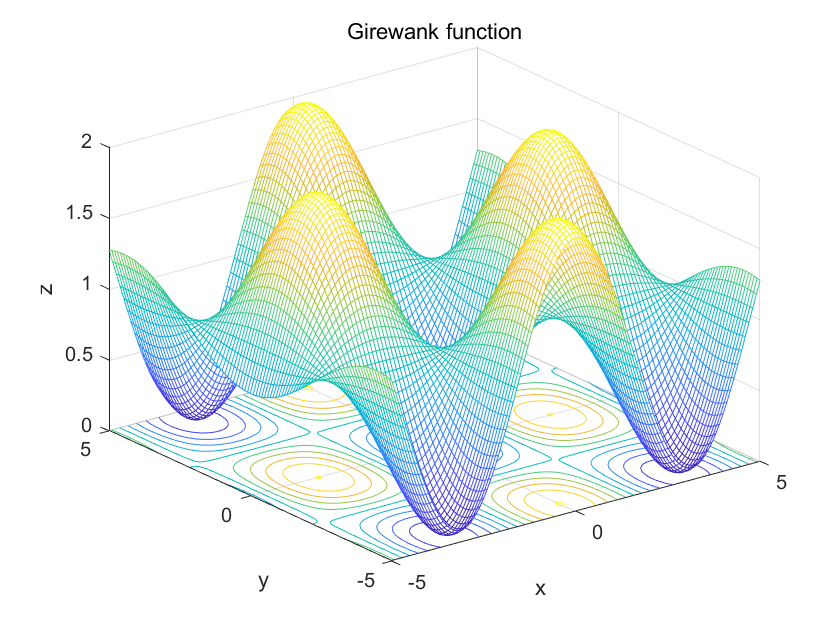

x = -5:0.1:5;
y = -5:0.1:5;
[X,Y] = meshgrid(x, y);
[n, m] = size(X);
vX = reshape(X, 1, m*n);
vY = reshape(Y, 1, m*n);
newX = [vX; vY];
vZ = Griewank(newX);    % 调用Griewank函数实现批量计算
Z = reshape(vZ, n, m);
figure(1)
meshc(X, Y, Z);
xlabel('x');
ylabel('y');
zlabel('z')
title('Girewank function');

(2) 请分别在$\left\lbrack -1000,1000\right\rbrack \times \left\lbrack -1000,1000\right\rbrack ,\left\lbrack -50,50\right\rbrack \times \left\lbrack -50,50\right\rbrack ,\left\lbrack -10,10\right\rbrack \times \left\lbrack -10,10\right\rbrack$和$\left\lbrack -5,5\right\rbrack \times \left\lbrack -5,5\right\rbrack$区域上绘制函数的曲面图（可以调用我的surf_func完成），并且用subplot将绘图结果组成一个$2\times 2$排列的四张小图构成的图。

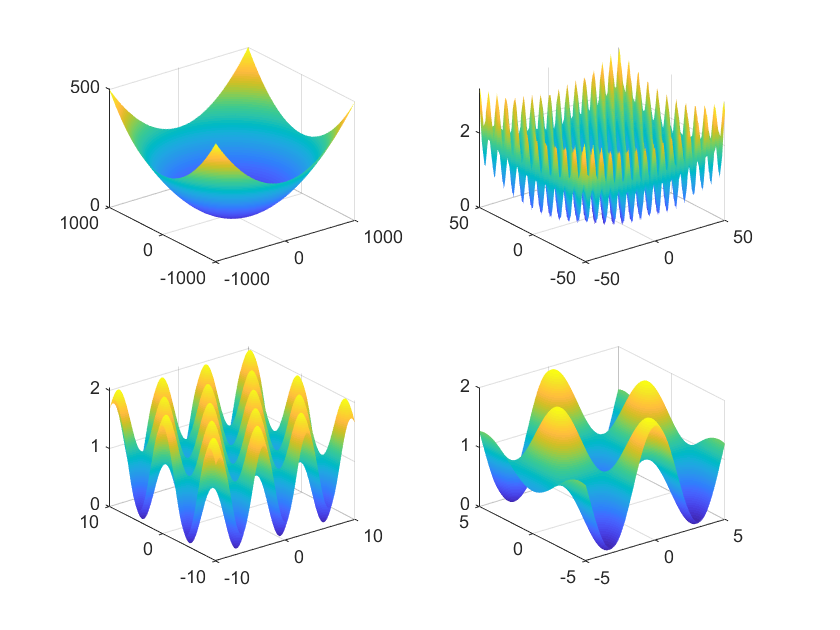

clf;
figure(2);

subplot(221);
surf_func(@Griewank, [-1000, 1000, -1000, 1000], 1);
shading interp;

subplot(222);
surf_func(@Griewank, [-50, 50, -50, 50], 1);
shading interp;

subplot(223);
surf_func(@Griewank, [-10, 10, -10, 10], 0.1);
shading interp;

subplot(224);
surf_func(@Griewank, [-5, 5, -5, 5], 0.1);
shading interp;

(3) 编写Matlab函数计算Griewank的梯度和海森矩阵，请附至多不超过一页A4的报告详细描述你的输入输出设计和这么做的理由。

首先给出Griewank函数梯度和Hessian矩阵的定义式，如下所示：


$$\frac{\partial }{\partial x_i }f\left(x\right)=\frac{x_i }{2000}+\frac{1}{\sqrt{i}}\mathrm{sin}\left(\frac{x_i }{\sqrt{i}}\right)\prod_{j=1,j\not= i}^n \mathrm{cos}\left(\frac{x_j }{\sqrt{j}}\right)=\frac{x_i }{2000}+\frac{1}{\sqrt{i}}\mathrm{tan}\left(\frac{x_i }{\sqrt{i}}\right)\prod_{j=1}^n \mathrm{cos}\left(\frac{x_j }{\sqrt{j}}\right);$$


$\frac{\partial^{2}}{\partial x_{i} \partial x_{j}} f(x)$$=$$-\frac{1}{\sqrt{i}}\mathrm{sin}\left(\frac{x_i }{\sqrt{i}}\right)\frac{1}{\sqrt{j}}\mathrm{sin}\left(\frac{x_j }{\sqrt{j}}\right)\prod_{k=1,k\not= i,k\not= j}^n \mathrm{cos}\left(\frac{x_j }{\sqrt{j}}\right)=\;-\frac{1}{\sqrt{i}}\frac{1}{\sqrt{j}}\mathrm{tan}\left(\frac{x_i }{\sqrt{i}}\right)\mathrm{tan}\left(\frac{x_j }{\sqrt{j}}\right)\prod_{k=1}^n \mathrm{cos}\left(\frac{x_j }{\sqrt{j}}\right)\;,j\not= i$;


$$\frac{\partial^2 }{\partial {x_i }^2 }f\left(x\right)=\frac{1}{2000}+$$

$$\frac{1}{i}\prod_{j=1}^n \mathrm{cos}\left(\frac{x_j }{\sqrt{j}}\right);$$


可以看到上述偏导或者二阶偏导的表达式中均含义一个公共累乘项，在具体的计算程序中可以简化计算步骤。

对于梯度和Hessian矩阵计算程序的输入输出设计详见附件报告说明。

为方便绘图，下面以二元变量情形为实例（即n=2），并且验证对于批量计算的支持：

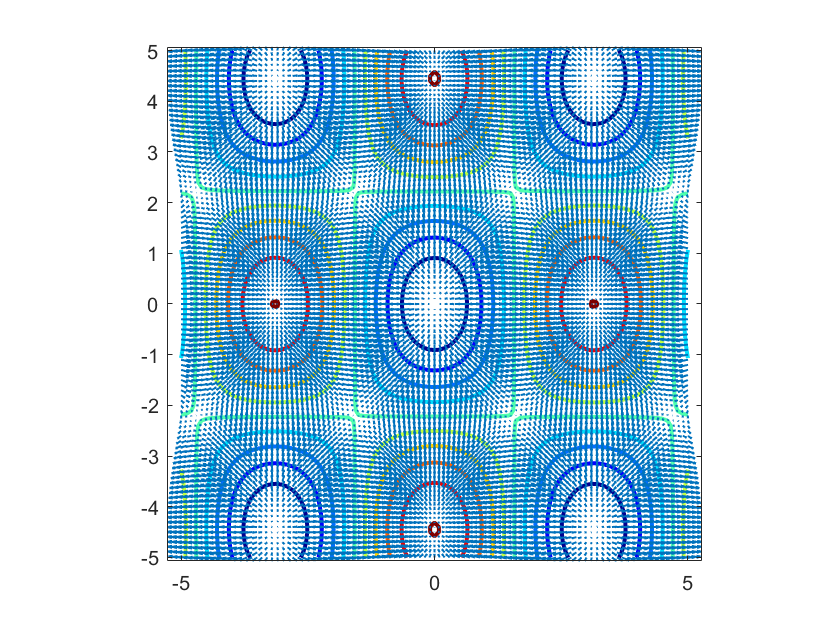

% 以下验证Matlab自带函数的计算结果
clf;
[X,Y] = meshgrid(-5:.1:5);
Z = (X.^2 + Y.^2) / 4000 - cos(X).*cos(Y/sqrt(2)) + 1;
[DX,DY] = gradient(Z,.1,.1);
contour(X,Y,Z,'LineWidth',2)
colormap jet
hold on
quiver(X,Y,DX,DY,2,'LineWidth',1)
axis equal
hold off

% 验证自己编写的函数与MATLAB集成的结果是否一致
x = -5:0.1:5;
y = -5:0.1:5;
[X, Y] = meshgrid(x, y);
[xN, yN] = size(X);
vX = reshape(X, 1, xN*yN);
vY = reshape(Y, 1, xN*yN);
fX = [vX; vY];
vZ = Gradient_Griewank(fX);     % 调用Gradient_Griewank函数实现梯度的批量计算
U = reshape(vZ(1, :), yN, xN);
V = reshape(vZ(2, :), yN, xN);
format short
abs(U-DX)

ans =     0.0116    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0013    0.0013    0.0012    0.0011    0.0009    0.0008    0.0007    0.0005    0.0004    0.0002    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0014    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0007    0.0006    0.0005    0.0003    0.0002
    0.0119    0.0016    0.0016    0.0016    0.0016    0.0015    0.0015    0.0014    0.0014    0.0013    0.0012    0.0011    0.0010    0.0008    0.0007    0.0006    0.0004    0.0002    0.0001    0.0001    0.0002    0.0004    0.0005    0.0007    0.0008    0.0009    0.0011    0.0012    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0016    0.0015    0.0015    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0008    0.0006    0.0005    0.0003   

由于Matlab自带gradient函数为数值梯度，即相邻元素值差分，所以与我自己写的准确表达式有一定差距。

下面验证我自己实现的梯度计算函数与MATLAB自带函数准确计算结果的差距：

syms x y;
f = (x^2 + y^2) / 4000 - cos(x)*cos(y/sqrt(2)) + 1;
dfx = diff(f,x);
dfy = diff(f,y);
x = vX;
y = vY;
dfx = eval(dfx);
dfx = reshape(dfx(1, :), yN, xN);
abs(U-dfx)

ans = 	1.0e+-15 *

    0.2220    0.3331    0.3331    0.3331    0.2220    0.2220    0.2220    0.2220    0.1110    0.1110    0.3331    0.2220    0.1110    0.0555    0.1110    0.1110    0.0555    0.0278    0.0139    0.0139    0.0278    0.0555    0.0555    0.1110    0.1665    0.2220    0.1110    0.1110    0.2220    0.1110    0.1110    0.3331    0.2220    0.1110    0.2220    0.1110    0.3331    0.1110    0.1110    0.2220    0.3331         0         0    0.1110    0.1110    0.1110         0    0.0555    0.0278    0.0278
    0.1110    0.3331    0.3331    0.3331    0.1110    0.2220    0.2220    0.1110    0.2220    0.2220    0.3331    0.2220    0.2220    0.1110    0.1110    0.1110    0.0555    0.0278    0.0069    0.0069    0.0278    0.0555    0.0555    0.0555    0.2220    0.2220    0.2220    0.1110    0.1110    0.1110    0.2220    0.3331    0.2220    0.2220         0    0.1110    0.3331    0.1110    0.2220    0.1110    0.2220    0.1110    0.1110         0         0    0.1110         0    0.0555

忽略计算误差，从以上结果可以看出我此处实现的批量梯度计算结果正确。

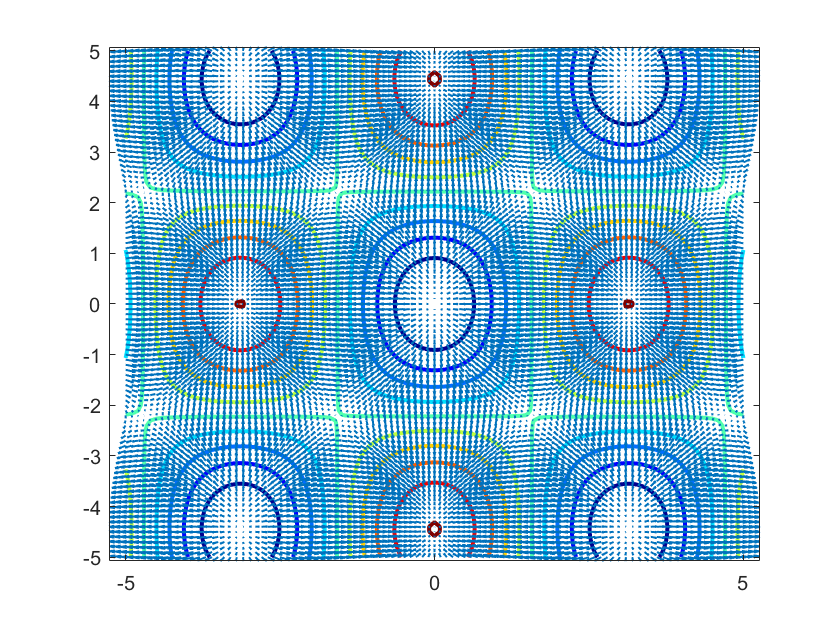


% 将自己计算的梯度矩阵绘图 
clf;
figure()
contour(X,Y,Z,'LineWidth',2)
colormap jet
hold on
quiver(X,Y,U,V,2,'LineWidth',1)

将我自己写的梯度计算函数绘制成图，可见与Matlab自带函数结果一致。

下面对Hessian矩阵的计算进行验证：

x_ = -0.5:0.1:0.5;
y_ = -0.5:0.1:0.5;
H_ = Hessian_Griewank([x_; y_])     % 调用Hessian_Griewank函数批量计算Hessian矩阵

H_ = H_(:,:,1) =

    0.8238   -0.1174
   -0.1174    0.4122


H_(:,:,2) =

    0.8850   -0.0768
   -0.0768    0.4427


H_(:,:,3) =

    0.9344   -0.0440
   -0.0440    0.4675


H_(:,:,4) =

    0.9708   -0.0198
   -0.0198    0.4856


H_(:,:,5) =

    0.9930   -0.0050
   -0.0050    0.4968


H_(:,:,6) =

    1.0005         0
         0    0.5005


H_(:,:,7) =

    0.9930   -0.0050
   -0.0050    0.4968


H_(:,:,8) =

    0.9708   -0.0198
   -0.0198    0.4856


H_(:,:,9) =

    0.9344   -0.0440
   -0.0440    0.4675


H_(:,:,10) =

    0.8850   -0.0768
   -0.0768    0.4427


H_(:,:,11) =

    0.8238   -0.1174
   -0.1174    0.4122


由于Matlab自带的hessian函数只能计算符号表达式，所以对于批量计算的验证需要做一些变换：

syms x y;
f = (x^2 + y^2) / 4000 - cos(x)*cos(y/sqrt(2)) + 1;
h = hessian(f, [x, y])

$$h = \left(\begin{array}{cc} \cos\left(\frac{\sqrt{2}\,y}{2}\right)\,\cos\left(x\right)+\frac{1}{2000} & -\frac{\sqrt{2}\,\sin\left(\frac{\sqrt{2}\,y}{2}\right)\,\sin\left(x\right)}{2}\\ -\frac{\sqrt{2}\,\sin\left(\frac{\sqrt{2}\,y}{2}\right)\,\sin\left(x\right)}{2} & \frac{\cos\left(\frac{\sqrt{2}\,y}{2}\right)\,\cos\left(x\right)}{2}+\frac{1}{2000} \end{array}\right)$$

n = size(x_, 2);
H = zeros(2, 2, n);
for i = 1:n
    x = x_(i);
    y = y_(i);
    H(:, :, i) = eval(h);
end
H

H = H(:,:,1) =

    0.8238   -0.1174
   -0.1174    0.4122


H(:,:,2) =

    0.8850   -0.0768
   -0.0768    0.4427


H(:,:,3) =

    0.9344   -0.0440
   -0.0440    0.4675


H(:,:,4) =

    0.9708   -0.0198
   -0.0198    0.4856


H(:,:,5) =

    0.9930   -0.0050
   -0.0050    0.4968


H(:,:,6) =

    1.0005         0
         0    0.5005


H(:,:,7) =

    0.9930   -0.0050
   -0.0050    0.4968


H(:,:,8) =

    0.9708   -0.0198
   -0.0198    0.4856


H(:,:,9) =

    0.9344   -0.0440
   -0.0440    0.4675


H(:,:,10) =

    0.8850   -0.0768
   -0.0768    0.4427


H(:,:,11) =

    0.8238   -0.1174
   -0.1174    0.4122


上述测试中，输出的维度均设计为$n\;\mathrm{rows}\times n\;\mathrm{columns}\times m\;\mathrm{pages}$，也就是说输出的H(:, :, i)表示第i个处的Hessian矩阵计算结果。

format short;
H - H_

ans = ans(:,:,1) =

   1.0e-16 *

         0   -0.4163
   -0.4163         0


ans(:,:,2) =

   1.0e-15 *

   -0.1110   -0.0278
   -0.0278   -0.0555


ans(:,:,3) =

   1.0e-16 *

         0   -0.1388
   -0.1388         0


ans(:,:,4) =

     0     0
     0     0


ans(:,:,5) =

   1.0e-17 *

         0    0.0867
    0.1735         0


ans(:,:,6) =

     0     0
     0     0


ans(:,:,7) =

   1.0e-17 *

         0    0.0867
    0.1735         0


ans(:,:,8) =

     0     0
     0     0


ans(:,:,9) =

   1.0e-16 *

         0   -0.1388
   -0.1388         0


ans(:,:,10) =

   1.0e-15 *

   -0.1110   -0.0278
   -0.0278   -0.0555


ans(:,:,11) =

   1.0e-16 *

         0   -0.4163
   -0.4163         0


忽略计算误差，从以上结果可以看出我此处实现的Hessian矩阵计算结果正确，并且具有批量计算的能力。